clear;
close all;
clc;


Load Data

load([fileparts(pwd) '\OUTPUT\SumVar.mat']);
SNRcolor='rgb';
SNRs=[-6 0 6];


SNR env vs. Normalized Driven Rate

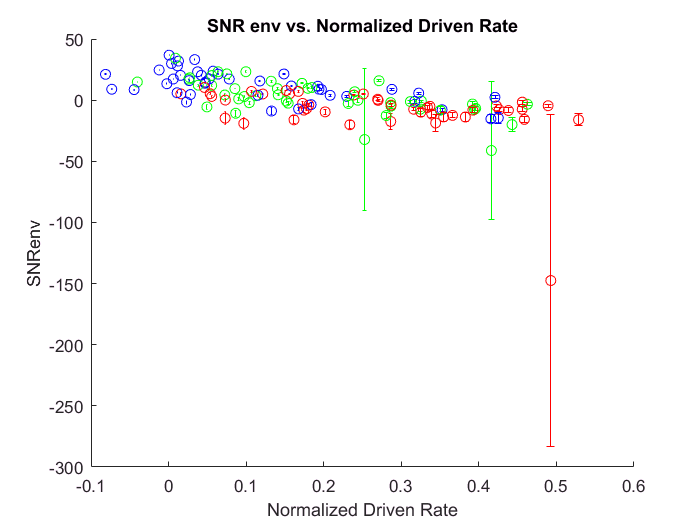

hold on;
for i=1:length(SumVar)
    x=(SumVar(i).spkRateSN-SumVar(i).SR)/(SumVar(i).SatR-SumVar(i).SR);
    y=SumVar(i).SNRenvAll;
    
    errorbar(x, mean(y), std(y), [SNRcolor(SumVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Normalized Driven Rate');
ylabel('SNRenv');
title('SNR env vs. Normalized Driven Rate');

SNR env vs. Driven Rate

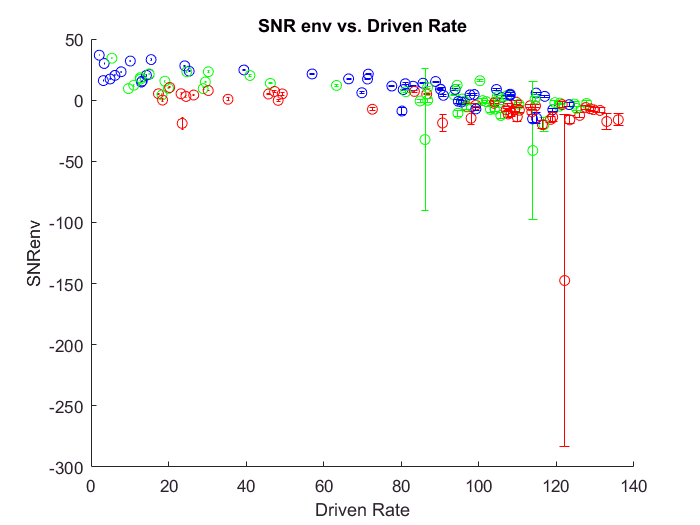

figure;
hold on;
for i=1:length(SumVar)
    y=SumVar(i).SNRenvAll;
    errorbar(SumVar(i).spkRateSN, mean(y), std(y), [SNRcolor(SumVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('Driven Rate');
ylabel('SNRenv');
title('SNR env vs. Driven Rate');

STA Filtered Acoustic SNRenv vs. Neural SNRenv

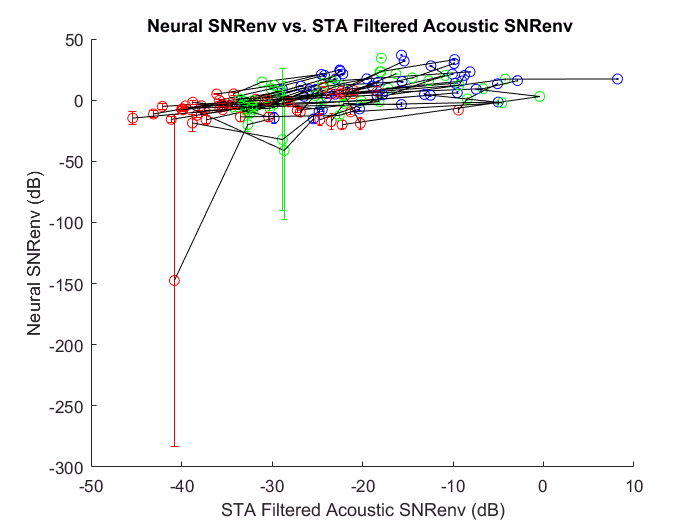

figure;

CurLineAcousticSNRenv=[];
CurLineNeuralSNRenv=[];
CFprev=nan;
SPLprev=nan;

hold on;
for i=1:length(SumVar)
    y=SumVar(i).SNRenvAll;
    
    if SumVar(i).BF_TC~=CFprev || SumVar(i).SPL~=SPLprev % Means new line to plot
        if i~=1
            SumVar(i-3).SNRenvSlope=(CurLineNeuralSNRenv(end)-CurLineNeuralSNRenv(1))/(CurLineAcousticSNRenv(end)-CurLineAcousticSNRenv(1));
            SumVar(i-2).SNRenvSlope=SumVar(i-3).SNRenvSlope;
            SumVar(i-1).SNRenvSlope=SumVar(i-3).SNRenvSlope;

            SumVar(i-3).SNRenvSlopeLeft=(CurLineNeuralSNRenv(2)-CurLineNeuralSNRenv(1))/6;
            SumVar(i-3).SNRenvSlopeRight=(CurLineNeuralSNRenv(end)-CurLineNeuralSNRenv(2))/6;
            SumVar(i-3).SNRenvSlopeTotal=(CurLineNeuralSNRenv(end)-CurLineNeuralSNRenv(1))/12;
               
            SumVar(i-2).SNRenvSlopeLeft=SumVar(i-3).SNRenvSlopeLeft;
            SumVar(i-2).SNRenvSlopeRight=SumVar(i-3).SNRenvSlopeRight;
            SumVar(i-2).SNRenvSlopeTotal=SumVar(i-3).SNRenvSlopeTotal;
            
            SumVar(i-1).SNRenvSlopeLeft=SumVar(i-3).SNRenvSlopeLeft;
            SumVar(i-1).SNRenvSlopeRight=SumVar(i-3).SNRenvSlopeRight;
            SumVar(i-1).SNRenvSlopeTotal=SumVar(i-3).SNRenvSlopeTotal;
        end
        
        plot(CurLineAcousticSNRenv,CurLineNeuralSNRenv,'k');
        %         pause;
        %         plot(CurLineAcousticSNRenv,CurLineNeuralSNRenv,'c');
        CurLineAcousticSNRenv=SumVar(i).SNRenvACST;
        CurLineNeuralSNRenv=mean(y);
        
    else
        CurLineAcousticSNRenv=[CurLineAcousticSNRenv, SumVar(i).SNRenvACST];
        CurLineNeuralSNRenv=[CurLineNeuralSNRenv, mean(y)];
    end
    CFprev=SumVar(i).BF_TC;
    SPLprev=SumVar(i).SPL;
    
    errorbar(SumVar(i).SNRenvACST, mean(y), std(y), [SNRcolor(SumVar(i).SNR==SNRs) 'o']);
end

for i=1:length(SumVar)
    if isempty(SumVar(i).SNRenvSlope)
        SumVar(i).SNRenvSlope=nan;
    end
end

hold off;
xlabel('STA Filtered Acoustic SNRenv (dB)');
ylabel('Neural SNRenv (dB)');
title('Neural SNRenv vs. STA Filtered Acoustic SNRenv ');

Tuning Curve BF vs REVCOR BF

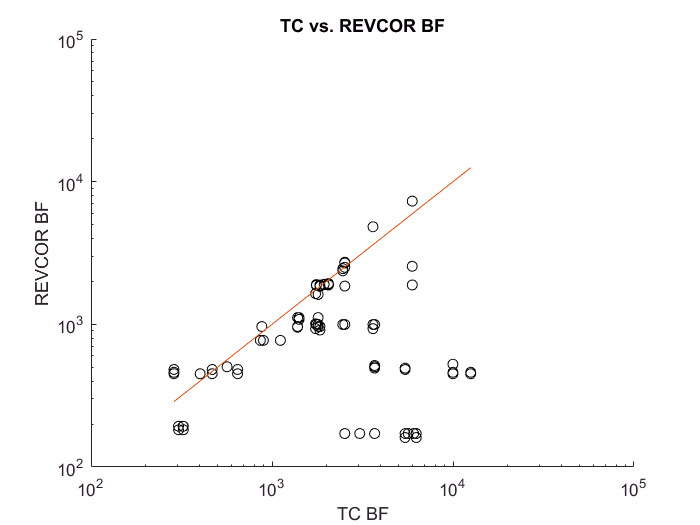

scatter([SumVar.BF_TC],[SumVar.BF_revcor],'k');
set(gca,'xscale','log','yscale','log');
hold on;
BF_TC=extractfield(SumVar, 'BF_TC');
plot([min(BF_TC) max(BF_TC)], [min(BF_TC) max(BF_TC)]);
xlabel('TC BF');
ylabel('REVCOR BF');
title('TC vs. REVCOR BF');

SNRenv vs CF

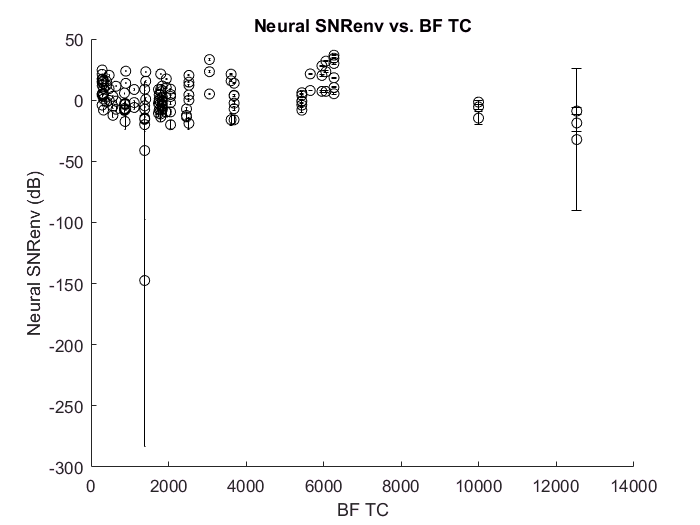

figure;
hold on;
for i=1:length(SumVar)
    y=SumVar(i).SNRenvAll;
    errorbar(SumVar(i).BF_TC, mean(y), std(y), 'ko');
end
hold off;
xlabel('BF TC');
ylabel('Neural SNRenv (dB)');
title('Neural SNRenv vs. BF TC');

SNRenv vs. Total Spike for computing SNRenv

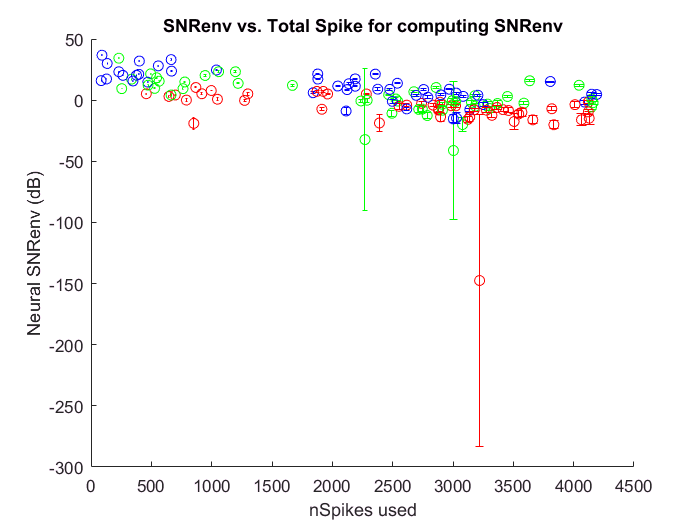

figure;
hold on;
for i=1:length(SumVar)
    y=SumVar(i).SNRenvAll;
    errorbar(SumVar(i).nSpikesSN, mean(y), std(y), [SNRcolor(SumVar(i).SNR==SNRs) 'o']);
end
hold off;
xlabel('nSpikes used');
ylabel('Neural SNRenv (dB)');
title('SNRenv vs. Total Spike for computing SNRenv');

SNRenv vs. Q10 from TC

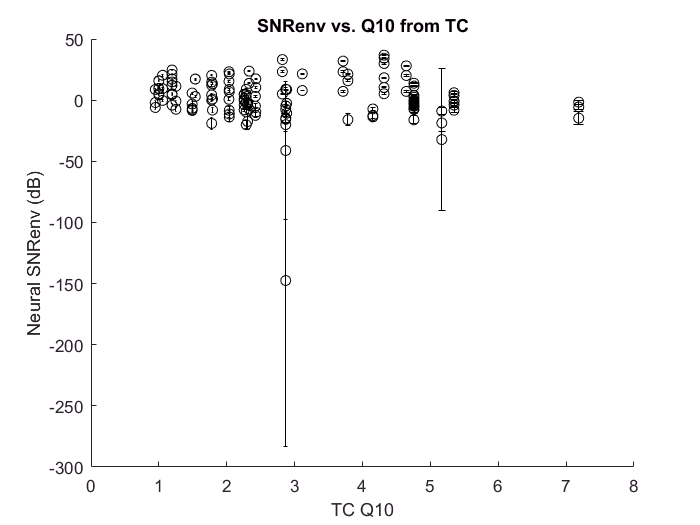

figure;
hold on;
for i=1:length(SumVar)
    y=SumVar(i).SNRenvAll;
    if SumVar(i).Q10_TC<25
        errorbar(SumVar(i).Q10_TC, mean(y), std(y), 'ko');
    end
end
hold off;
xlabel('TC Q10');
ylabel('Neural SNRenv (dB)');
title('SNRenv vs. Q10 from TC');

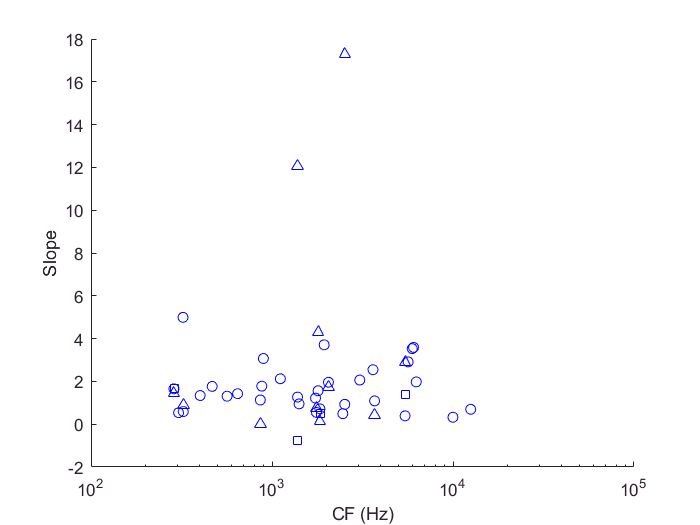

bftc=extractfield(SumVar,'BF_TC')';
slopes=extractfield(SumVar,'SNRenvSlope')';
spls=extractfield(SumVar,'SPL')';

bftc_slopes_spls=unique([bftc, slopes, spls],'rows');
bftc_slopes_spls(isnan(bftc_slopes_spls(:,2)),:)=[];

prev_spl=nan;
shapes='o^sp';
uniq_cfs=unique(bftc_slopes_spls(:,1));
figure; 
hold on;
for i=1:length(uniq_cfs)
    cur_cf=uniq_cfs(i);
    cur_ind=find(bftc_slopes_spls(:,1)==cur_cf);
    cur_slopes=bftc_slopes_spls(cur_ind,2);
    cur_spl=bftc_slopes_spls(cur_ind,3);
    [~,sort_ind]=sort(cur_spl);
    sort_slopes=cur_slopes(sort_ind);
    for j=1:length(sort_slopes)
        plot(cur_cf, sort_slopes(j),'b', 'marker', shapes(j));
    end
end
set(gca,'xscale','log')

xlabel('CF (Hz)');
ylabel('Slope');